clear all
close all
clc

load concrete_data.mat

ConcreteData2 = table2array(ConcreteData2);
concrete_data = abs(ConcreteData2);
minimo = min(min(concrete_data));
maximo = max(max(concrete_data));
concrete_data = concrete_data - minimo;
concrete_data = concrete_data/(maximo - minimo);

clear ConcreteData2 minimo maximo;

%% Redução de dimensionalidade
colunas= 4;
[coeff,score,latent,tsquared,explained,mu] = pca(concrete_data(:,1:end-1));
sum(explained(1:colunas))

ans = 86.7099

concrete_data = [score(:,1:colunas) concrete_data(:,end)];

len = size(concrete_data);
[l c] = size(concrete_data);
%50% treinamento 50%teste
trnData = concrete_data(1:l*0.5,:);
chkData = concrete_data((l*0.5)+1:end,:);


%Clusterização FCM - gera antecedentes da regra
inmftype = 'gaussmf';
numMFs = 3*ones(1 , size(concrete_data,2)-1);
outmftype = 'linear';
fismat = genfis1(trnData,numMFs,inmftype,outmftype);


%Ajustando parametros conseguentes da regura
%e fazendo ajuste fino dos antecedentes
[fismat1,error1,ss,fismat2,error2] = anfis(trnData,fismat,[500],[],chkData);


ANFIS info: 
	Number of nodes: 193
	Number of linear parameters: 405
	Number of nonlinear parameters: 24
	Total number of parameters: 429
	Number of training data pairs: 515
	Number of checking data pairs: 515
	Number of fuzzy rules: 81


Start training ANFIS ...

   1 	 0.00597474 	 0.224637
   2 	 0.0058305 	 0.231099
   3 	 0.00569057 	 0.236174
   4 	 0.00556085 	 0.243522
   5 	 0.0054174 	 0.246672
Step size increases to 0.011000 after epoch 5.
   6 	 0.00518492 	 0.236947
   7 	 0.00501432 	 0.194063
   8 	 0.00507009 	 0.297047
   9 	 0.00476771 	 0.271229
  10 	 0.00500663 	 0.372187
  11 	 0.00468217 	 0.300786
Step size decreases to 0.009900 after epoch 11.
  12 	 0.00493236 	 0.38742
  13 	 0.00458066 	 0.35363
  14 	 0.00479919 	 0.379004
  15 	 0.00463942 	 0.390452
Step size decreases to 0.008910 after epoch 15.
  16 	 0.00475034 	 0.391832
  17 	 0.00455644 	 0.420715
  18 	 0.00470929 	 0.411202
  19 	 0.00453319 	 0.424313
Step size decreases to 0.008019 after epoch 

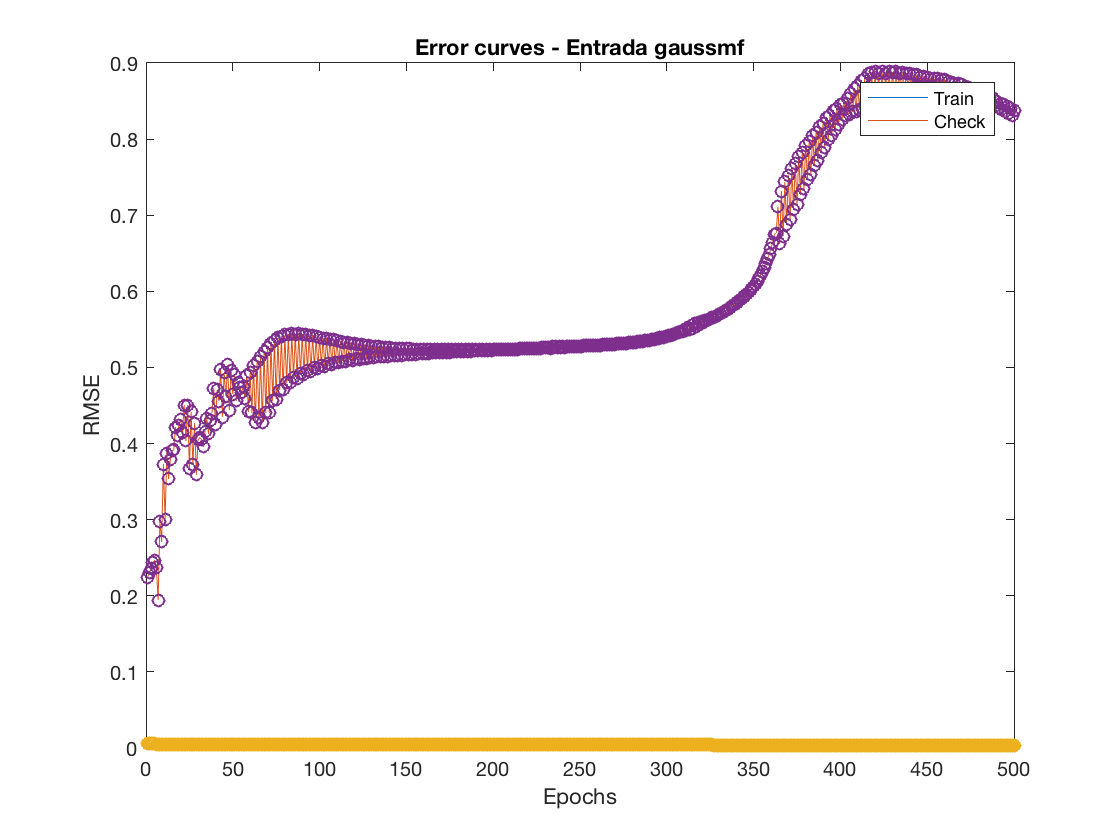


%Evolução erro treino e check
figure(2)
plot([error1,error2]);
hold on
plot([error1,error2],'o');
xlabel('Epochs');
ylabel('RMSE');
title('Error curves - Entrada gaussmf');
legend('Train','Check');


fprintf('Min erro: %0.4f\n',min(error1))

Min erro: 0.0038


[C,I] = min(error2);
fprintf('Min chkErr: %0.4f (%d)',C,I)

Min chkErr: 0.1941 (7)

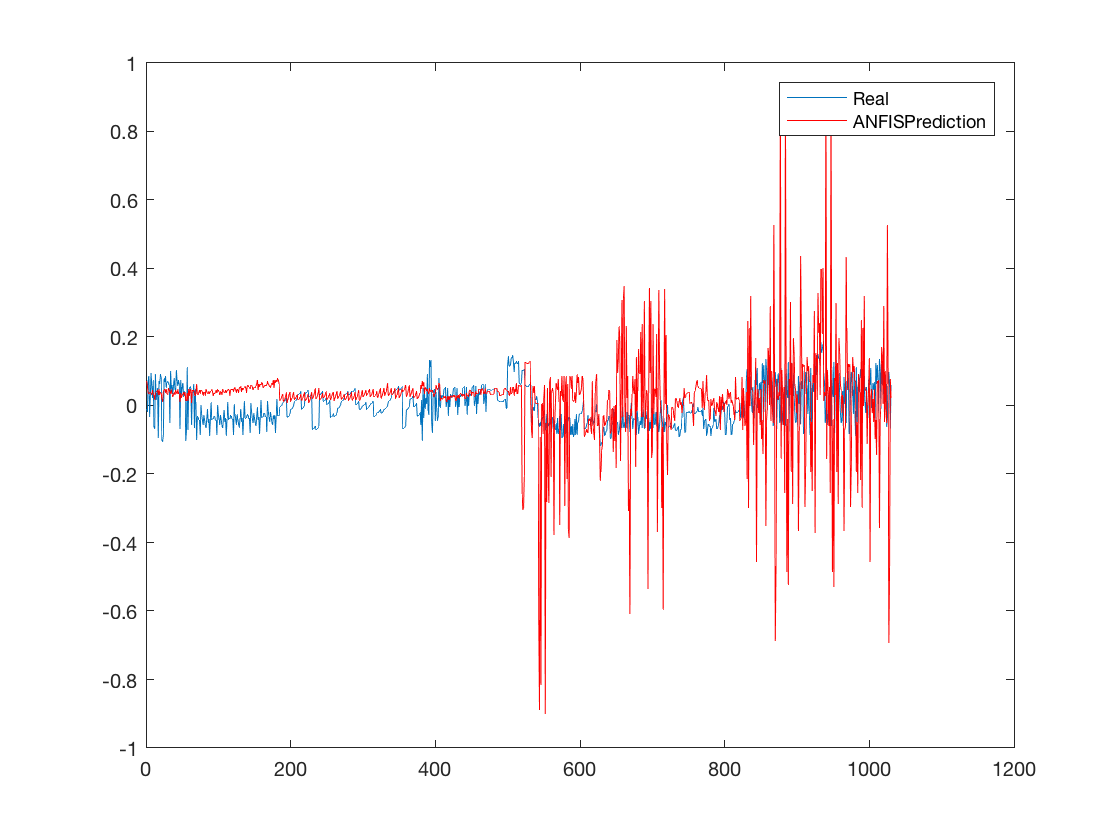


figure(3)
ANFISPrediction = evalfis([trnData(:,1:len(2)-1); chkData(:,1:len(2)-1)],fismat2);
plot(concrete_data(:,colunas));
hold on
plot(ANFISPrediction,'r');
legend('Real','ANFISPrediction')